# Tarea Semanal 4

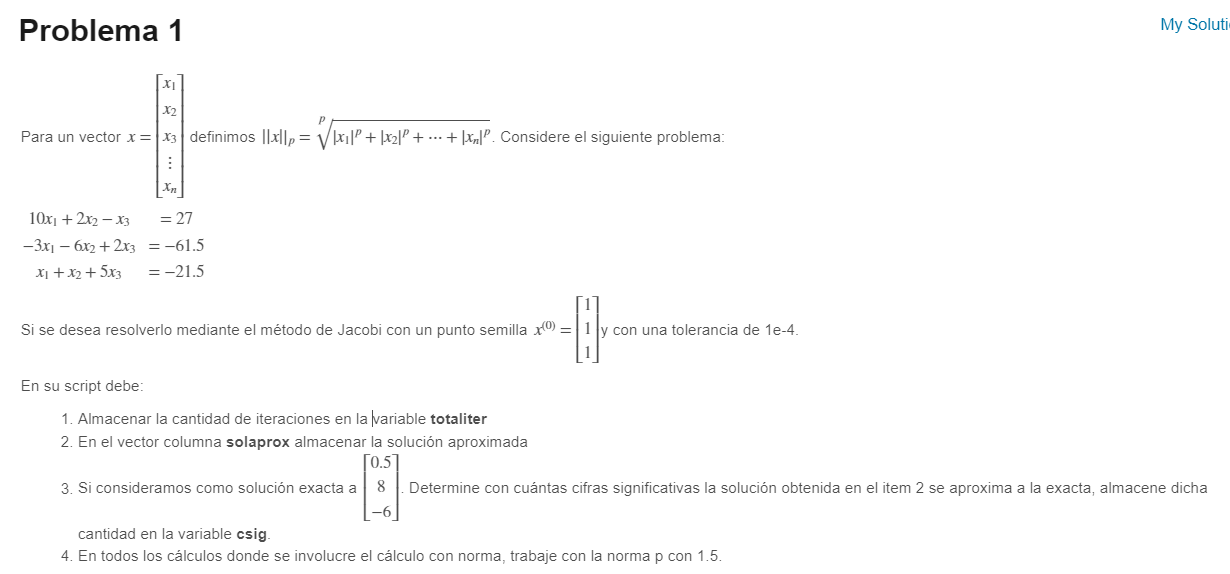

A = [10 2 -1; -3 -6 2; 1 1 5];
b = [27; -61.5; -21.5];
x0 = [1 1 1]';
Tol = 1e-4;

J = jacobi(A, b, x0, Tol);
[totaliter, ~] = size(J);
totaliter = totaliter - 1

totaliter =      9


solaprox = J(end, 1:3)'

solaprox =    0.500048611802469
   7.999948449053498
  -5.999892746567902


i = 0;

tope = 5*10^-i;
while err < tope
    i = i +1;
    tope = 5*10^-i;
end
csig = i-1

csig =      5


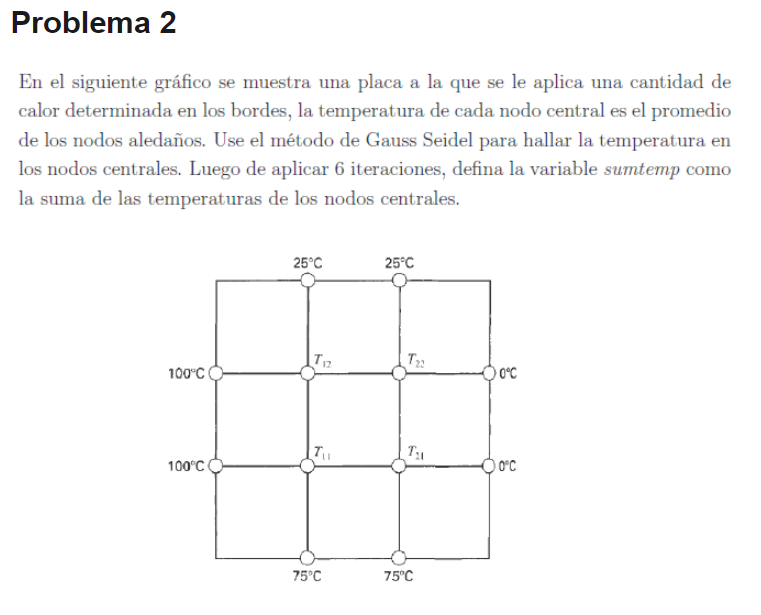

A = [4 -1 -1 0; -1 4 0 -1; -1 0 4 -1; 0 -1 -1 4];
b = [125; 25; 175; 75];
x0 = [0 0 0 0]';

z = gausseidel_it(A, b, x0, 6)

z =                    0                   0                   0                   0   1.000000000000000
  31.250000000000000  14.062500000000000  51.562500000000000  35.156250000000000   1.000000000000000
  47.656250000000000  26.953125000000000  64.453125000000000  41.601562500000000   0.254545454545455
  54.101562500000000  30.175781250000000  67.675781250000000  43.212890625000000   0.095238095238095
  55.712890625000000  30.981445312500000  68.481445312500000  43.615722656250000   0.023529411764706
  56.115722656250000  31.182861328125000  68.682861328125000  43.716430664062500   0.005865102639296
  56.216430664062500  31.233215332031250  68.733215332031250  43.741607666015625   0.001465201465201



sumtemp = sum(z(end, 1:4))

sumtemp =      1.999244689941406e+02


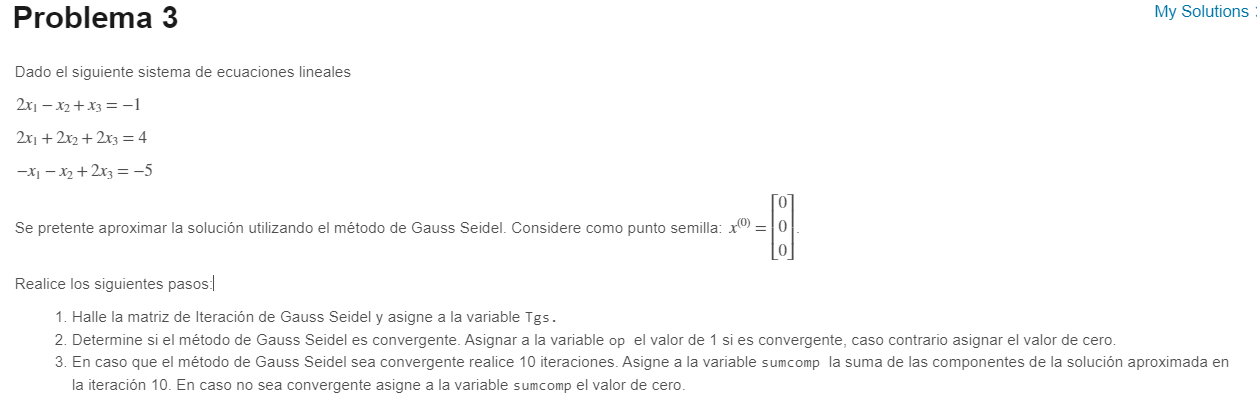

A = [2 -1 1; 2 2 2; -1 -1 2];
b = [-1; 4; -5];
x0 = [0 0 0]';

D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);

Tgs = inv(D-L)*U

Tgs =                    0   0.500000000000000  -0.500000000000000
                   0  -0.500000000000000  -0.500000000000000
                   0                   0  -0.500000000000000


re = radio_espectral(Tgs)

re =    0.500000000000000


if (re < 1)
    op = 1
else
    op = 0
end

op =      1


z = gausseidel_it(A, b, x0, 10);

sumcomp = sum(z(end,1:3))

sumcomp =    2.002929687500000


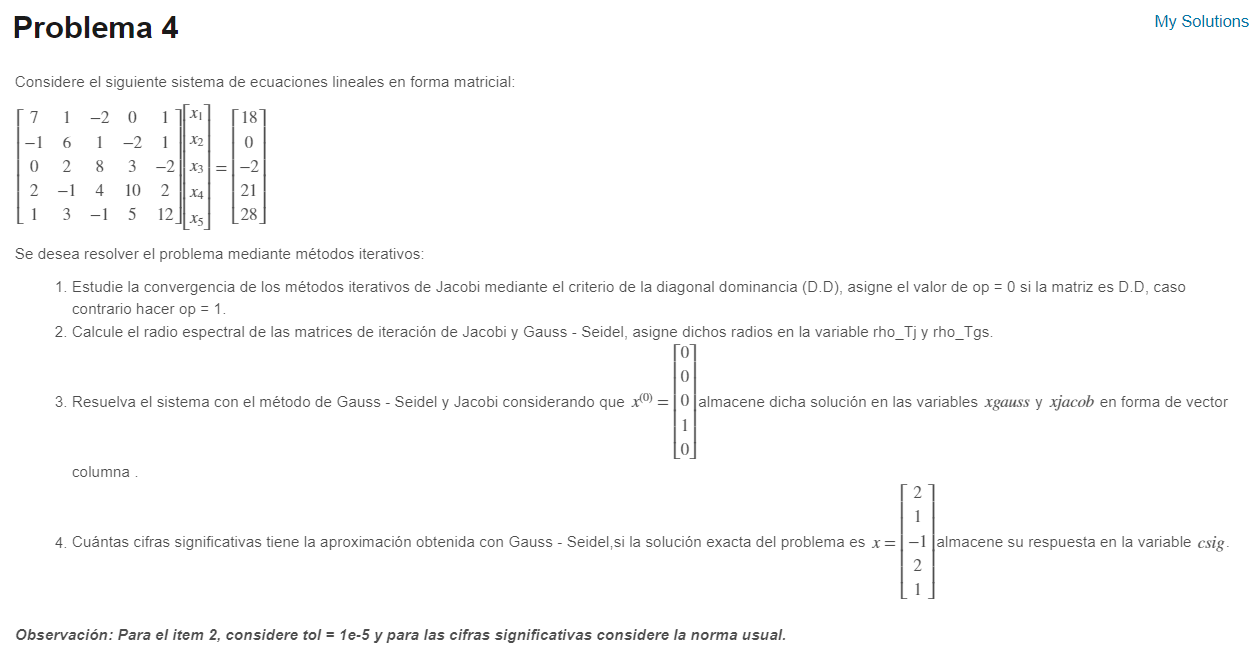

format long

A = [7 1 -2 0 1; -1 6 1 -2 1; 0 2 8 3 -2; 2 -1 4 10 2; 1 3 -1 5 12];
b = [18; 0; -2; 21; 28];
x0 = [0 0 0 1 0]';
Tol = 1e-5;

exacta = [2 1 -1 2 1]';

% 1
op = diagdom2(A)

op =      0


% 2
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);

Tj = inv(D) * (L + U);
Tgs = inv(D-L)*U;

rho_Tj = radio_espectral(Tj)

rho_Tj =    0.753777717492837


rho_Tgs = radio_espectral(Tgs)

rho_Tgs =    0.566297652292778


%3
J = jacobi(A, b, x0, Tol);
GS = gausseidel_tol(A, b, x0, Tol);

xjacob = J(end, 1:5)'

xjacob =    2.000018924419924
   0.999960795756410
  -0.999947561966723
   1.999950216284808
   1.000044226667756


xgauss = GS(end, 1:5)'

xgauss =    2.000011362917284
   0.999983201326279
  -0.999980086341345
   1.999983991502846
   1.000011582437359


%4
err = norm(exacta - xgauss, "inf")/norm(exacta,"inf");
i = 0;

tope = 5*10^-i;
while err < tope
    i = i +1;
    tope = 5*10^-i;
end
csig = i-1

csig =      5


   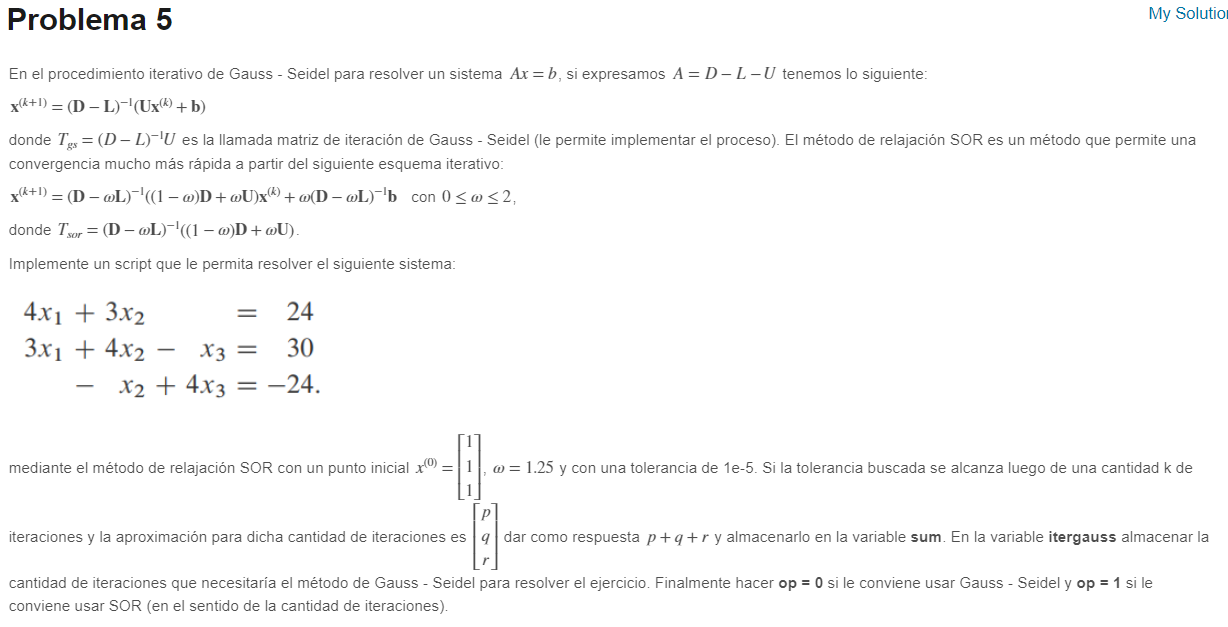

format long
A = [4 3 0; 3 4 -1; 0 -1 4];
b = [24; 30; -24];
x0 = [1 1 1]';
Tol = 1e-5;
w = 1.25;

SOR = relajacion_sor(A, b, x0, Tol, w);
[itersor, ~] = size(SOR);
itersor = itersor - 1

itersor =     10


sum = SOR(end, 1) + SOR(end, 2) + SOR(end, 3)

sum =    1.999994905421294


gauss = gausseidel_tol(A, b, x0, Tol);
[itergauss, ~] = size(gauss);
itergauss = itergauss - 1

itergauss =     18


if (itersor < itergauss)
    op = 1
else
    op = 0
end

op =      1


Función de Jacobi  [tolerancia]

function z = jacobi(A,b,x0,Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tj = inv(D)*(L+U);
    cj = inv(D)*b;

    error = 1;

    z = [x0' error];

    while error>Tol
        x1 = Tj*x0 + cj; 
        error = norm(x1-x0, 1.5)/norm(x1, 1.5);
        z = [z; x1' error];
        x0 = x1;
    end
end


Función para hallar las cifras significativas

function csig = cifras_significativas(x_aprox, x_exact)
    diferencia = norm(x_aprox - x_exact, 1.5);
    
    csig = floor(-log10(diferencia / norm(x_exact, 1.5)));
    
end

Función de Gauss Seidel [Iterativa]

function z = gausseidel_it(A, b, x0, iter)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tgs = inv(D-L)*U;
    cgs = inv(D-L)*b;
    error = 1;
    z=[x0' error];

    for i = 1:iter
        x1 = Tgs*x0+cgs;
        error = norm(x1-x0,inf)/norm(x1,inf);
        z = [z;x1' error];
        x0 = x1;
    end
end

Función de Gauss Seidel [tolerancia]

function z = gausseidel_tol(A, b, x0, Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tgs = inv(D-L)*U;
    cgs = inv(D-L)*b;
    error = 1;
    z=[x0' error];

    while error > Tol
        x1 = Tgs*x0 + cgs;
        error = norm(x1-x0,inf)/norm(x1,inf);
        z = [z;x1' error];
        x0 = x1;
    end
end

Función Diagonal Estrictamente Dominante 1

function op = diagdom1(A)
    % op = 1 si es Estrictamente Dominante
    % op = 0 si no lo es


    [m,n] = size(A);
    op = 1;
    
    if m == n
        for k = 1:m
            if abs(A(k,k)) <= sum(abs(A(k,:))) - abs(A(k,k))
                op = 0;
                break;
            end
        end
    end
end

Función Diagonal Estrictamente Dominante 2

function op = diagdom2(A)
    % op = 0 si es Estrictamente Dominante
    % op = 1 si no lo es


    [m,n] = size(A);
    op = 0;
    
    if m == n
        for k = 1:m
            if abs(A(k,k)) <= sum(abs(A(k,:))) - abs(A(k,k))
                op = 1;
                break;
            end
        end
    end
end

Función radio espectral

function re = radio_espectral(T)
    re = max(abs(eig(T)));
end

Método de relajación SOR

function z = relajacion_sor(A, b, x0, Tol, w)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tsor = inv(D - w.*L) * ((1 - w).*D + w.*U);
    csor = inv(D - w.*L) * w*b;

    error = 1;
    z=[x0' error];

    while error > Tol
        x1 = Tsor*x0 + csor;
        error = norm(x1-x0,inf)/norm(x1,inf);
        z = [z; x1' error];
        x0 = x1;
    end
end